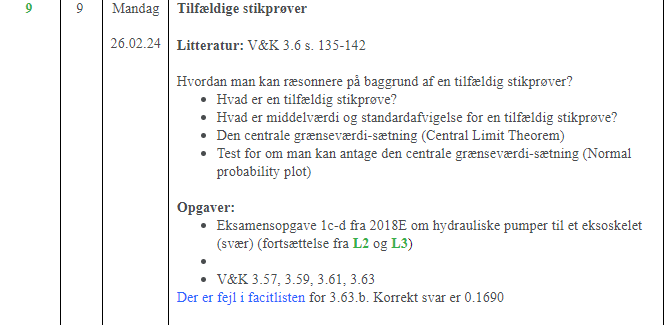

clc; clear;

n_samples =60

n_samples = 60

sample_size = 7

sample_size = 7

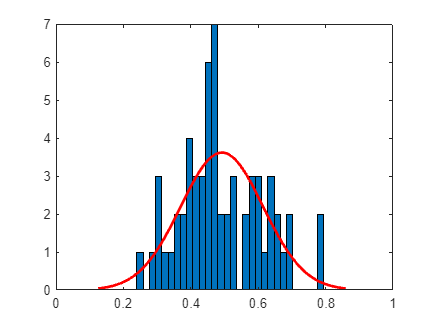



for i = 1:n_samples
    x(i) = mean(rand(sample_size,1));
end

figure
% histogram(x, 20)
histfit(x,30,"normal")

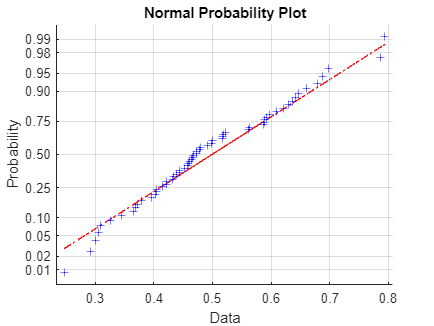

figure
normplot(x)

fitdist(x',"normal")

ans =   NormalDistribution

  Normal distribution
       mu = 0.492383   [0.460752, 0.524013]
    sigma = 0.122444   [0.103788, 0.149341]



var(x)

ans = 0.0150


[h,c,v,b] = vartest(x, 0.01)

h = 1

c = 0.0156

v =     0.0108    0.0223


b = struct with fields:
    chisqstat: 88.4565
           df: 59


clc; clear;

% Data indlæses
data = xlsread("Eksamenssæt\Eksamenssæt 2018E\Data_M4STI1_2018E (1).xlsx", 'A:A');

% Opgave a
D = sort(data)

D =     96
    97
   102
   102
   104
   106
   108
   110



n = length(D)       % Antal datapunkter

n = 8

mdl = mean(data)    % Stikprøvens middelværdi

mdl = 103.1250

stdafv = std(D)  % Populationsdata, derfor n-1

stdafv = 4.9407


afv = [mdl + stdafv; mdl - stdafv]

afv =   108.0657
   98.1843



max(D), min(D)

ans = 110

ans = 96


% Det ses at gennemsnittet +/- 1 standard afvigelse ligger indenfor rækkeviden min, max i datasættet

% Opgave b
D = data;
max(D)

ans = 110


stdafv = std(D)

stdafv = 4.9407


middel = mean(D)

middel = 103.1250

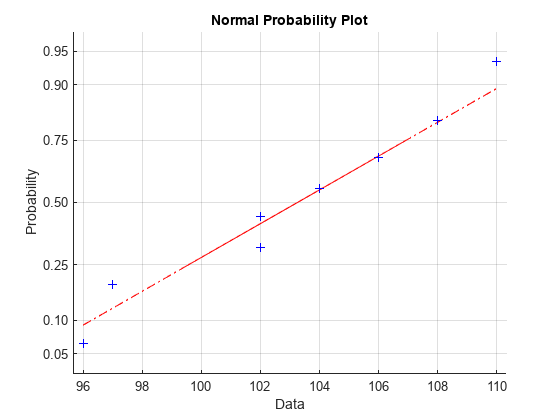


boxplot(D, 'Orientation','horizontal', 'Labels',{'Hydraulik data'})

histogram(D, floor(min(D)):2:ceil(max(D)))

stemleafplot(D)


prctile(D, [25,50,75])


% Opgave c
% Observerede værdier
mu_obs = 105;
std_obs = 5;

% Udregnede stikprøve værdier
Ybar = mdl;
std_obs = stdafv;

% Den centrale grænseværdisætning antages
Z = (Ybar - mu_obs)/(std_obs/sqrt(n))

Z = -1.0734


% P(Z >= -1.0734)
ssh1 = normcdf(Z) % Ssh for at den er større end

ssh1 = 0.1415

ssh2 = 1 - normcdf(abs(Z))

ssh2 = 0.1415

ssh3 = ssh1 + ssh2

ssh3 = 0.2831


losningsforslag = 2*(1-normcdf(abs(Z)))

losningsforslag = 0.2831

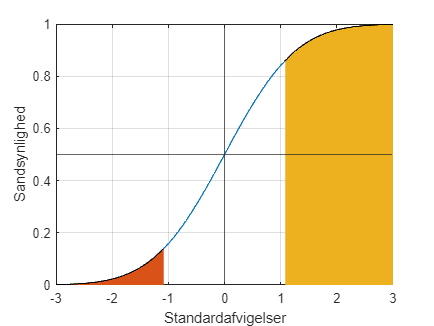

dist = makedist("Normal","mu",0,"sigma",1);
x = -3:0.01:3;

df = cdf(dist, x);
df1 = pdf(dist, x);

% Plot for forståelse
plot(x, df), xline(0), yline(0.5), grid(), xlabel("Standardafvigelser"), ylabel("Sandsynlighed")
hold on


x_less_Z = find(x < Z);
x_larger_Z = find(x > abs(Z));

% Komulativ fordelings plot
% mindre end Z
area(x(1, 1:length(x_less_Z)), df(1, 1:length(x_less_Z)));

% Større end Z
area(x(1, x_larger_Z(1):end), df(1, x_larger_Z(1):end));


hold off

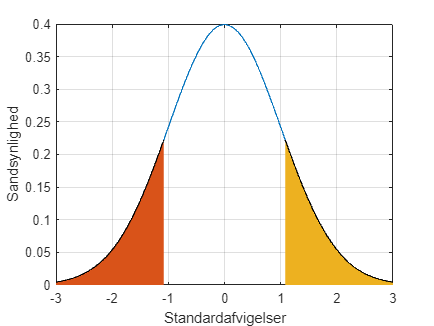


% Ssh plot
plot(x, df1), xlabel("Standardafvigelser"), ylabel("Sandsynlighed"), grid()
hold on
% mindre end Z
area(x(1, 1:length(x_less_Z)), df1(1, 1:length(x_less_Z)));

% Større end Z
area(x(1, x_larger_Z(1):end), df1(1, x_larger_Z(1):end));
hold off

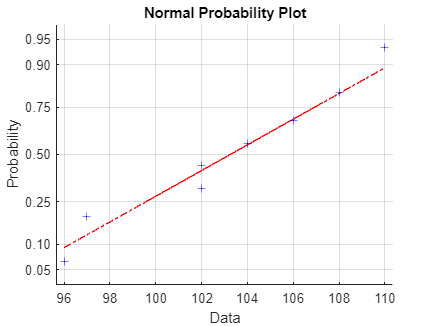


normplot(D)